# Author: Lu, Chia-Feng 2013.11.29

clear, close all
clc

## initialize parameters

path(path,'.\fastica_25');  % add FastICA path

samplerate = 1000; % in Hz
passband = [1 50];  % passband for bandpass filter
forder = 6; % filter order of IIR

ICNo=10;  % the specified number of independent components
PCNo=ICNo;  % the preserved number of PCs 
 
dispch=3;   % channel for plot
displength=2000; % data length for plot
rejectCorrThres=0.5;

chlabel={'F5','F3','F1','Fz','F2','F4','F6','P1','FC5','FC3','FC1','FCz','FC2','FC4','FC6','Pz','C5','C3','C1','Cz','C2','C4','C6','P2','CP5','CP3','CP1','CPz','CP2','CP4','CP6','POz'};

## load data

load('EEGdata.mat')

EEGdata=filter_2sIIR(EEGdata',passband,samplerate,forder,'bandpass');

% figure,
% for i=[1:5:32, 33 34]  % Ch.33 is the HEOG, Ch.34 is the VEOG
%     plot(EEGdata(i,1:displength))
%     pause
% end

## perform FastICA

[icasig, A, W] = fastica(EEGdata(1:32,:),'numOfIC',ICNo,'displayMode','off','firstEig',1,'lastEig',PCNo); % fast ICA

Number of signals: 32
Number of samples: 60000
Calculating covariance...
Reducing dimension...
Selected [ 10 ] dimensions.
Smallest remaining (non-zero) eigenvalue [ 3.98194 ]
Largest remaining (non-zero) eigenvalue [ 249.869 ]
Sum of removed eigenvalues [ 18.377 ]
[ 96.959 ] % of (non-zero) eigenvalues retained.
Whitening...
Check: covariance differs from identity by [ 2.22045e-15 ].
Used approach [ defl ].
Used nonlinearity [ pow3 ].
Starting ICA calculation...
IC 1 .......computed ( 7 steps ) 
IC 2 .................computed ( 17 steps ) 
IC 3 .............computed ( 13 steps ) 
IC 4 ..........computed ( 10 steps ) 
IC 5 .......................computed ( 23 steps ) 
IC 6 ......................computed ( 22 steps ) 
IC 7 ......................................................................................computed ( 86 steps ) 
IC 8 ...............computed ( 15 steps ) 
IC 9 .........................................................computed ( 57 steps ) 
IC 10 ..computed ( 2 steps ) 
D

% [icasig, A, W] = fastica(EEGdata(1:32,:),'numOfIC',ICNo,'displayMode','off'); % fast ICA
% [icasig, A, W] = fastica(EEGdata(1:32,:),'numOfIC',ICNo,'displayMode','off','interactivePCA','on'); % fast ICA

## identify the ICs dominated by EOG

rejectICA=[];
% find the icasig with high correlations with HEOG (ch.33)
R1=[];
for i=1:ICNo
    tmp=corrcoef(icasig(i,:),EEGdata(33,:));
    R1(i)=tmp(2);
end
rejectICA=find(abs(R1)>rejectCorrThres);
% find the icasig with high correlations with VEOG (ch.34)
R2=[];
for i=1:ICNo
    tmp=corrcoef(icasig(i,:),EEGdata(34,:));
    R2(i)=tmp(2);
end
rejectICA=[rejectICA find(abs(R2)>rejectCorrThres)];
rejectICA=unique(rejectICA); % 丟掉重複項
fprintf(['The icasig #' num2str(rejectICA) ' were rejected!\n'])

The icasig #2  5 were rejected!


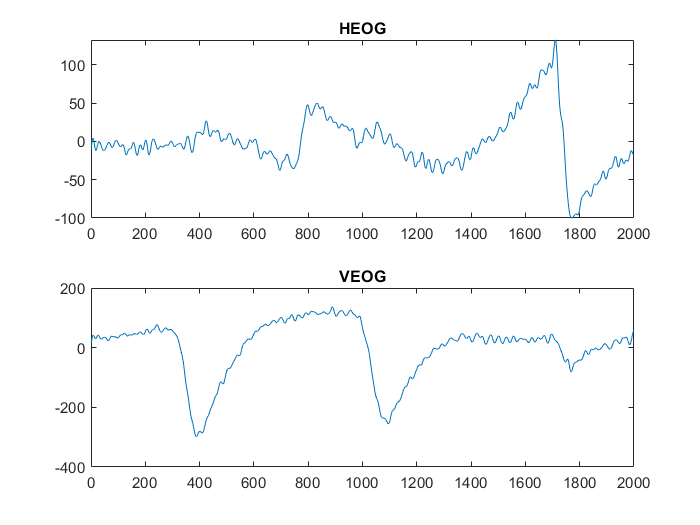


figure,
subplot(2,1,1),plot(EEGdata(33,1:displength)),title('HEOG') 
subplot(2,1,2),plot(EEGdata(34,1:displength)),title('VEOG')  

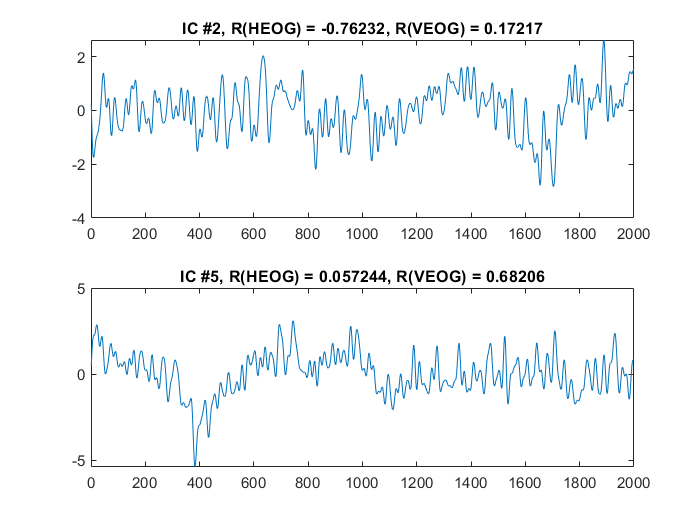


figure,
for i=1:length(rejectICA)
    subplot(length(rejectICA),1,i),plot(icasig(rejectICA(i),1:displength)) 
    title(['IC #' num2str(rejectICA(i)) ', R(HEOG) = ' num2str(R1(rejectICA(i))) ', R(VEOG) = ' num2str(R2(rejectICA(i)))])
end

## reconstruct signal with out EOG ICs

A2=A;
icasig2=icasig;

## reconstruct the signal

A2(:,rejectICA)=[];
icasig2(rejectICA,:)=[];

newEEGdata=(A2*icasig2);

## compare EEG siganl before and after ICA

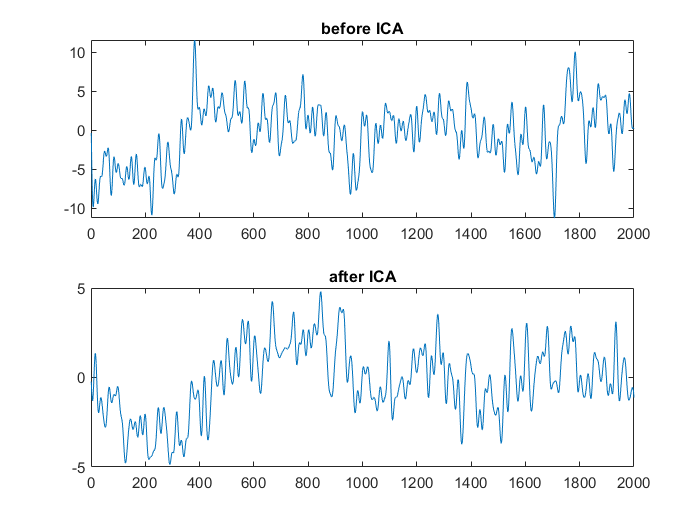

figure,
subplot(2,1,1),plot(EEGdata(dispch,1:displength)),title('before ICA')
subplot(2,1,2),plot(newEEGdata(dispch,1:displength)),title('after ICA')